# 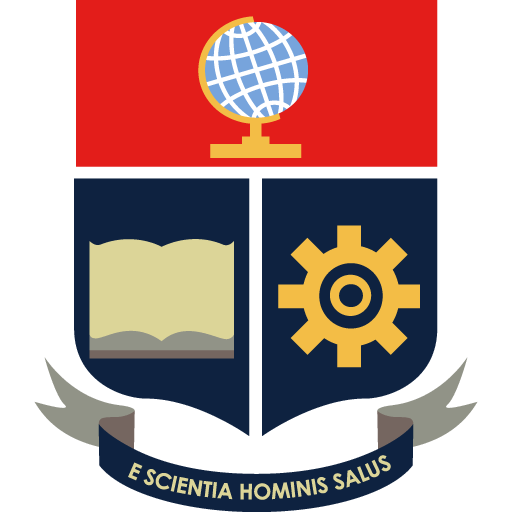

# **Movimiento**

- Asegúrese de estar utilizando el brazalete Myo Armband.

### `Comandos de la IMU`

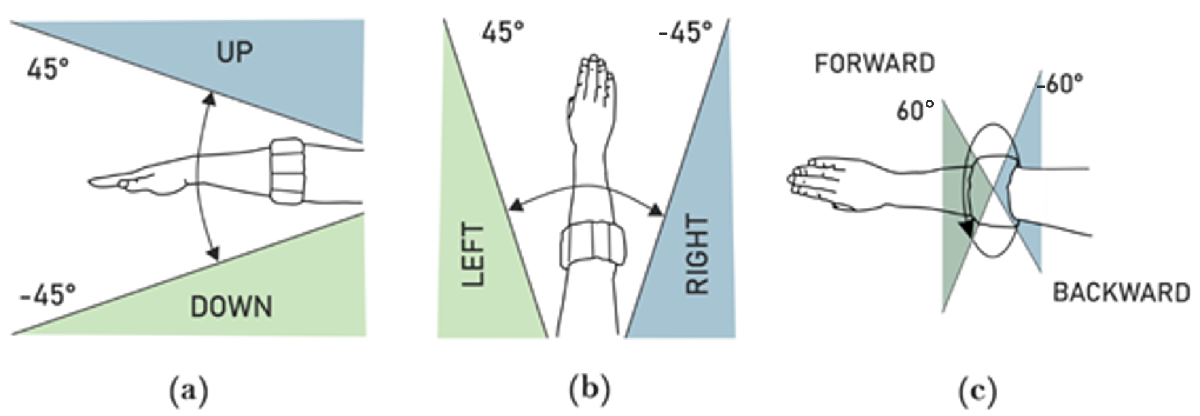

- Límites del ángulo euler **(a)** Pitch **(b)** Yaw **(c)** Roll

### `Movimientos en el plano`

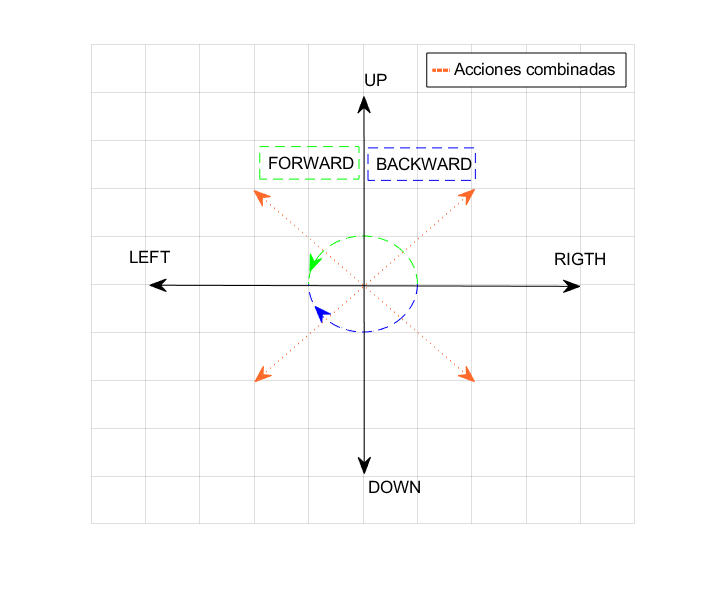

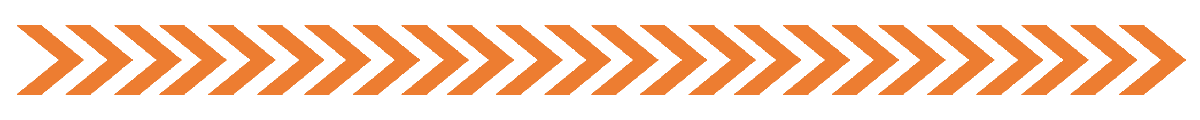

Calibrando...



Inicio de toma de datos


Listo...



Inicio de toma de datos
In Yaw limits
In Pitch limits
In Roll limits

Inicio de toma de datos
In Yaw limits
In Pitch limits
Dentro


Simulación terminada en: 49.78


Inicio de toma de datos
Right
In Pitch limits
In Roll limits


Simulación terminada en: 0.17

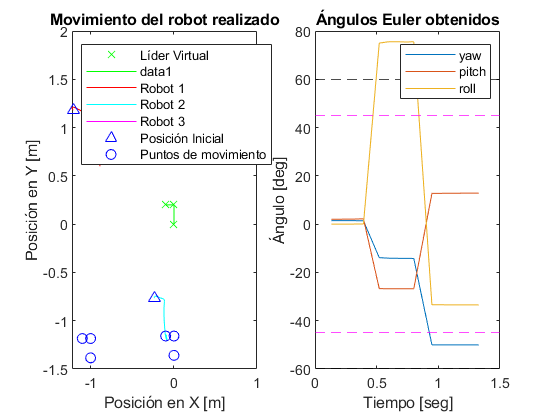

Goal=0.035;
mov=1;
ind1=1;
option=6;
first=1;
if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end
pause(0.1);

% install_myo_mex; % adds directories to MATLAB search path
% % install_myo_mex save % additionally saves the path
% sdk_path = 'C:\myo-sdk-win-0.9.0'; % root path to Myo SDK
% build_myo_mex(sdk_path); % builds myo_mex

% while option~=6
% out0=sim('paraprueba.slx');
% end

%(Inicio) Elección para comenzar o regresar a menu
while option~=4
if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
end
printStatus (1,'',ind1)
if option==3%FistRef1
%(Ref1)Ejecución de la interfaz de Simulink y cambio de formación

vectorx=zeros(1,15);
vectory=zeros(1,15);
vectrx1=zeros(1,15);vectry1=zeros(1,15);
vectrx2=zeros(1,15);vectry2=zeros(1,15);
vectrx3=zeros(1,15);vectry3=zeros(1,15);
posicionx1=zeros(1,15);posiciony1=zeros(1,15);
posicionx2=zeros(1,15);posiciony2=zeros(1,15);
posicionx3=zeros(1,15);posiciony3=zeros(1,15);
T_imu=[];
euAng=[];
i=1;
j=1;
mn=1;
n=1;
k=1;
ref1=1;
tiempo_union=0;

while option ~=4
%lectura del gesto
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    ref1=2;%ya ha leido un gesto tras entrar
    switch option
        case 1
            gesim="1.png";gesto="Gesto - Wave out";
        case 2
            gesim="2.png";gesto="Gesto - Wave in";
        case 3
            gesim="3.png";gesto="Gesto - Fist";
        case 4
            gesim="4.png";gesto="Gesto - Open";
        case 5
            gesim="5.png";gesto="Gesto - Pinch";
        otherwise
            gesim="6.png";gesto="Relajado - No Gesture";
    end
    else
        if ref1==1
            option=0;
        end
    end
    %fin de lectura del gesto
if first==1
    fprintf('Calibrando...\n')
    run GetIMU.m
    yaw_ref=yaw;
    pitch_ref=pitch;
    roll_ref=roll;
    first=0;
    pause(0.1);
    fprintf('Listo...\n')
end
run movimiento.m

if yaw_order~=0||pitch_order~=0||roll_order~=0
    tiempo=simtime(end)/0.1; % valor en paced simulation
    tiempoROS=rostime(end)-rostime(1);
    printStatus(2,tiempoROS,1)
end

%   Guardar datos
    vectorx(i)=x;
    vectory(i)=y;
    vectrx1(i)=vectorx(i)+rx1;vectry1(i)=vectory(i)+ry1;
    vectrx2(i)=vectorx(i)+rx2;vectry2(i)=vectory(i)+ry2;
    vectrx3(i)=vectorx(i)+rx3;vectry3(i)=vectory(i)+ry3;
    i=i+1;
    for jj=1:length(PosX1)
    posicionx1(j)=PosX1(jj);
    posiciony1(j)=PosY1(jj);
    j=j+1;
    end
    for mm=1:length(PosX2)
    posicionx2(mn)=PosX2(mm);
    posiciony2(mn)=PosY2(mm);
    mn=mn+1;
    end
    for nn=1:length(PosX3)
    posicionx3(n)=PosX3(nn);
    posiciony3(n)=PosY3(nn);
    n=n+1;
    end
    for mm=1:length(timeIMU)
    T_imu(k,:)=timeIMU(mm,:)+tiempo_union;
    euAng(k,:)=eulerAngles(mm,:);
    k=k+1;
    end
    tiempo_union=T_imu(k-1);

pause(0.4);

    %lectura del gesto
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    ref1=2;%ya ha leido un gesto tras entrar
    else
        if ref1==1
            option=0;
        end
    end
    %fin de lectura del gesto
%fin de contenido de while
end


%encerando angulos
euAng(:,1)=euAng(:,1)-yaw_ref*ones(length(euAng(:,1)),1);
euAng(:,2)=euAng(:,2)-pitch_ref*ones(length(euAng(:,2)),1);
euAng(:,3)=euAng(:,3)-roll_ref*ones(length(euAng(:,3)),1);

resmov=figure('Name','Resultados','NumberTitle','off','Color','w');
        subplot(1,2,1)
        plot(vectorx,vectory,'gx','DisplayName','Líder Virtual')
        hold on
        line(vectorx,vectory,'Color','g')
        plot(posicionx1,posiciony1,'r','DisplayName','Robot 1')
        plot(posicionx2,posiciony2,'c','DisplayName','Robot 2')
        plot(posicionx3,posiciony3,'m','DisplayName','Robot 3')
        plot(posicionx1(1),posiciony1(1),'b^','DisplayName','Posición Inicial')
        plot(posicionx2(1),posiciony2(1),'b^','HandleVisibility','off')
        plot(posicionx3(1),posiciony3(1),'b^','HandleVisibility','off')
        plot(vectrx1(1),vectry1(1),'bo','DisplayName','Puntos de movimiento')
        plot(vectrx1,vectry1,'bo','HandleVisibility','off')
        plot(vectrx2,vectry2,'bo','HandleVisibility','off')
        plot(vectrx3,vectry3,'bo','HandleVisibility','off')
        line(vectorx,vectory,'Color','g','HandleVisibility','off')
        xlabel('Posición en X [m]')
        ylabel('Posición en Y [m]')
        legend('Location','northwest')
        title('Movimiento del robot realizado')

        subplot(1,2,2)
        plot(T_imu,euAng); title('Ángulos Euler obtenidos'); 
        hold on 
        yline(45,'Color','m','LineStyle','--');yline(-45,'Color','m','LineStyle','--','HandleVisibility','off');
        yline(60,'Color','k','LineStyle','--');yline(-60,'Color','k','LineStyle','--','HandleVisibility','off');
        legend('yaw','pitch','roll');
        xlabel('Tiempo [seg]')
        ylabel('Ángulo [deg]')
option=0;
ind1=2;

%(FistRef1 End)
end

%(Inicio End)
end

disp("Saliendo de Movimiento")

Saliendo de Movimiento


pause(1)
open("menu.mlx")

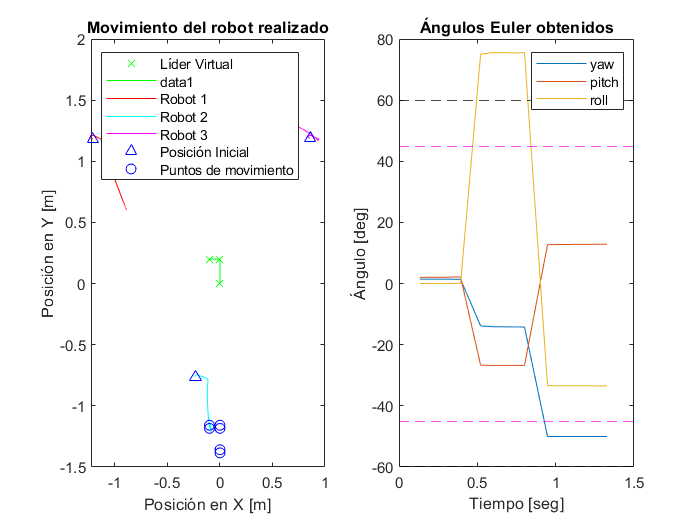

 
% vectrx1=vectorx(1,2:end)+rx1*ones(1,length(vectorx)-1);
% vectry1=vectory(1,2:end)+ry1*ones(1,length(vectory)-1);
% vectrx2=vectorx(1,2:end)+rx2*ones(1,length(vectorx)-1);
% vectry2=vectory(1,2:end)+ry2*ones(1,length(vectory)-1);
% vectrx3=vectorx(1,2:end)+rx3*ones(1,length(vectorx)-1);
% vectry3=vectory(1,2:end)+ry3*ones(1,length(vectory)-1);
%encerando angulos
if euAng(1,1)~=0
    euAng(:,1)=euAng(:,1)-yaw_ref*ones(length(euAng(:,1)),1);
    euAng(:,2)=euAng(:,2)-pitch_ref*ones(length(euAng(:,2)),1);
    euAng(:,3)=euAng(:,3)-roll_ref*ones(length(euAng(:,3)),1);
end
resmov=figure('Name','Resultados','NumberTitle','off','Color','w');
set(gcf,'Visible','on')
        subplot(1,2,1)
        plot(vectorx,vectory,'gx','DisplayName','Líder Virtual')
        hold on
        line(vectorx,vectory,'Color','g')
        plot(posicionx1,posiciony1,'r','DisplayName','Robot 1')
        plot(posicionx2,posiciony2,'c','DisplayName','Robot 2')
        plot(posicionx3,posiciony3,'m','DisplayName','Robot 3')
        plot(posicionx1(1),posiciony1(1),'b^','DisplayName','Posición Inicial')
        plot(posicionx2(1),posiciony2(1),'b^','HandleVisibility','off')
        plot(posicionx3(1),posiciony3(1),'b^','HandleVisibility','off')
        plot(vectrx1(1),vectry1(1),'bo','DisplayName','Puntos de movimiento')
        plot(vectrx1,vectry1,'bo','HandleVisibility','off')
        plot(vectrx2,vectry2,'bo','HandleVisibility','off')
        plot(vectrx3,vectry3,'bo','HandleVisibility','off')
        line(vectorx,vectory,'Color','g','HandleVisibility','off')
        xlabel('Posición en X [m]')
        ylabel('Posición en Y [m]')
        legend('Location','northwest')
        title('Movimiento del robot realizado')

        subplot(1,2,2)
        plot(T_imu,euAng); title('Ángulos Euler obtenidos'); 
        hold on 
        yline(45,'Color','m','LineStyle','--');yline(-45,'Color','m','LineStyle','--','HandleVisibility','off');
        yline(60,'Color','k','LineStyle','--');yline(-60,'Color','k','LineStyle','--','HandleVisibility','off');
        legend('yaw','pitch','roll');
        xlabel('Tiempo [seg]')
        ylabel('Ángulo [deg]')

option=0;
ind1=2;
pause(2)
% close('Resultados')

function printStatus (type,mssg,ind)
if type==1%Nivel seleccionado
    if ind == 1
        txt='Para empezar el movimiento haga el gesto Fist o su comando de referencia equivalente\n\nPare regresar el menú realizar Open o su equivalente\n';
         fprintf('Para empezar el movimiento haga el gesto Fist o su comando de referencia equivalente\n\nPare regresar el menú realizar Open o su equivalente\n');
         for i=1:strlength(txt)
             fprintf('\b');
         end
     else
        % Each \b removes one character from the previous fprintf.
        txt='Para mover la formación realizar Fist o su equivalente\nPare regresar el menú realizar Open o su equivalente\n';
        fprintf('Para mover la formación realizar Fist o su equivalente\nPare regresar el menú realizar Open o su equivalente\n');
        for i=1:strlength(txt)
             fprintf('\b');
         end
     end
elseif type==2%Tiempo simulación
     if ind == 1
         % The very first time we don't need to delete the old text
         fprintf('Simulación terminada en: %.2f', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bSimulación terminada en: %.2f', mssg);
     end
end
end